# Automatic Flight Control of F8-Crusader

**Control Objective: **

track a specific trajectory of the angle of attack.

**System:** 

States: $x_1$ is the angle of attack (rad), $x_2$ is the pitch angle (rad), $x_3$ is the pitch rate (rad/s ) 

Control input: $u$ is the control input representing the tail deflection angle (rad)

Reference: $r\left(t\right)$is the commanded angel of attack to be tracked

Outputs: assume full-state feedback (all states can be measured directly)

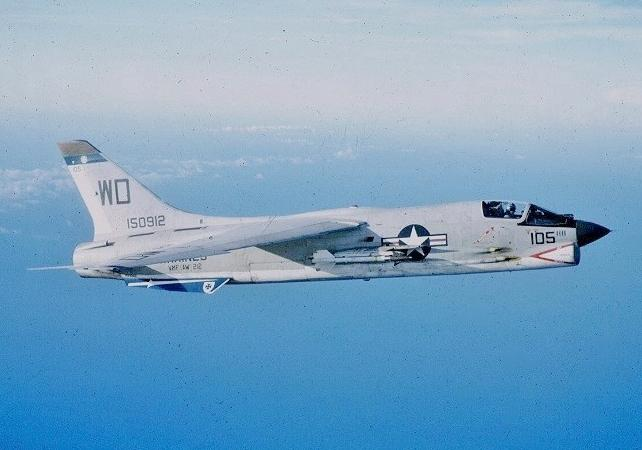

## Setting of Workflow

clear all, close all, clc
figpath = './FIGURES/F8/';
datapath = './DATA/F8/';
paths = {figpath, datapath};
for p = 1:length(paths)
    if ~exist(paths{p}, 'dir')
        mkdir(paths{p});
    end
end
addpath('./utils/');
addpath('./EX_FLIGHT_CONTROL_F8/');

SystemModel = 'F8';
Nvar = 3; % number of states

## Generating True Function Evaluations (Noise-Free Data)

InputSignalType = 'sine3'; % define type of control input to apply, u %'sine2'; sine3, %prbs; noise; sine2; sphs; 
ONLY_TRAINING_LENGTH = 1; % ?
ENSEMBLE_DATA = 0; % don't use ensemble learning methods
% generate training and validation data and plot control input and state
% time series
getTrainingData 

u = u'; % control input time series

## SINDYc Modelling

### Computing SINDYc model

% Parameters
ModelName = 'SINDYc'; 
polyorder = 3; % define order of polynomial for library of canditate functions
usesine = 0; % ?
% lambda_vec = [.01,.01,0.1]; % sphs // WORKED IN MPC
lambda_vec = [.0001,.01,0.01]; % define sparsity regularization cnostants to test, sine2 // WORKED IN MPC
eps = 0; % define noise to add to true function values

%Add noise
%eps = 0.05*std(x(:,1));
%x = x + eps*randn(size(x));       

% train the SINDYc model and return coefficients for each term in the
% library of canditate functions for each state
trainSINDYc

coefficients = 35×5 table
    Canditate Functions      xdot       ydot      zdot      udot
    ___________________    _________    ____    ________    ____

          {'1'  }                  0     0             0     0  
          {'x'  }             -0.877     0        -4.208     0  
          {'y'  }                  0     0             0     0  
          {'z'  }                  1     1        -0.396     0  
          {'u'  }             -0.215     0       -20.967     0  
          {'xx' }            0.46999     0      -0.46997     0  
          {'xy' }                  0     0             0     0  
          {'xz' }          -0.088006     0             0     0  
          {'xu' }                  0     0             0     0  
          {'yy' }             -0.019     0             0     0  
          {'yz' }      

### Predicting over Training Phase

% compute the state trajectory based on SINDYc model over training phase
if any(strcmp(InputSignalType,{'sine2', 'chirp','prbs', 'sphs'})==1)
    [tSINDYc, xSINDYc] = ode45(@(t,x) sparseGalerkinControl(t, x, forcing(x,t), Xi(:,1:Nvar), polyorder, usesine), tspan, x0,options);  % approximate
else
    p = struct;
    p.ahat = Xi(:,1:Nvar);
    p.polyorder = polyorder;
    p.usesine = usesine;
    p.dt = dt;
    [N,Ns] = size(x);
    xSINDYc = zeros(Ns,N); xSINDYc(:,1) = x0';
    for ct=1:N-1
        xSINDYc(:,ct+1) = rk4u(@sparseGalerkinControl_Discrete,xSINDYc(:,ct),u(ct),dt,1,[],p);
    end
    xSINDYc = xSINDYc'; % ?
end


### Validation

% setup figure
clear ph
figure, box on,
ccolors = get(gca,'colororder');
ccolors_valid = [ccolors(1,:)-[0 0.2 0.2];ccolors(2,:)-[0.1 0.2 0.09];ccolors(3,:)-[0.1 0.2 0.09]];

% plot the measurements of each state over time
for i = 1:Nvar
    ph(i) = plot(tspan, x(:,i),'-','Color',ccolors(i,:),'LineWidth',1); hold on
end

% plot the SINDYc estimates of each state over time
for i = 1:Nvar
    ph(Nvar+i) = plot(tspan, xSINDYc(:,i),'--','Color',ccolors_valid(i,:),'LineWidth',2);
end

ylim([-0.8 0.9])
xlabel('Time, $t$', 'Interpreter', 'latex')
ylabel('States, $x_i(t)$', 'Interpreter', 'latex')
title('Function Measurements (solid) and SINDYc Estimates (dashed)')
legend(ph([1,4]),'True',ModelName)
legend(ph([1,2,3]),'angle of attack','pitch angle', 'pitch rate')
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose', '-cmyk', [figpath,'EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.eps']);

### Validation

% Truth
tspanV   = [100:dt:200];
xA      = xv; % validation data
tA      = tv; % validation time phase

% Model
% compute the state trajectory based on SINDYc model over validation phase
if any(strcmp(InputSignalType,{'sine2', 'chirp','prbs', 'sphs'})==1)
    % predict system trajectory over validation time phase
    [tB, xB] = ode45(@(t,x) sparseGalerkinControl(t, x, forcing(x,t), Xi(:,1:Nvar), polyorder, usesine), tspanV, x(end,:), options);  % approximate
    xB = xB(2:end,:);
    tB = tB(2:end);  
else
    [N,Ns] = size(xA);
    xB = zeros(Ns,N); xB(:,1) = x(end,:)';
    for ct=1:N
        xB(:,ct+1) = rk4u(@sparseGalerkinControl_Discrete,xB(:,ct),uv(ct),dt,1,[],p);
    end
    xB = xB(:,1:N+1)';
    tB = tspanV(1:end);
end

### Plot Training and Validation Phases

u = u';
VIZ_SI_Validation

### Save Data

Model.name = 'SINDYc';
Model.polyorder = polyorder;
Model.usesine = usesine;
Model.Xi = Xi;
Model.dt = dt;
save(fullfile(datapath,['EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.mat']),'Model')

## MPC Simulation

## DMD